Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:53 |        3.91% |       23.33% |       3.9625 |       3.4617 |          0.0010 |
|      17 |          50 |       00:32:17 |      100.00% |       96.67% |       0.0006 |       0.1290 |          0.0010 |
|      30 |          90 |       00:58:46 |      100.00% |       96.67% |       0.0002 |       0.1257 |          0.0010 |
|=========================================================================================

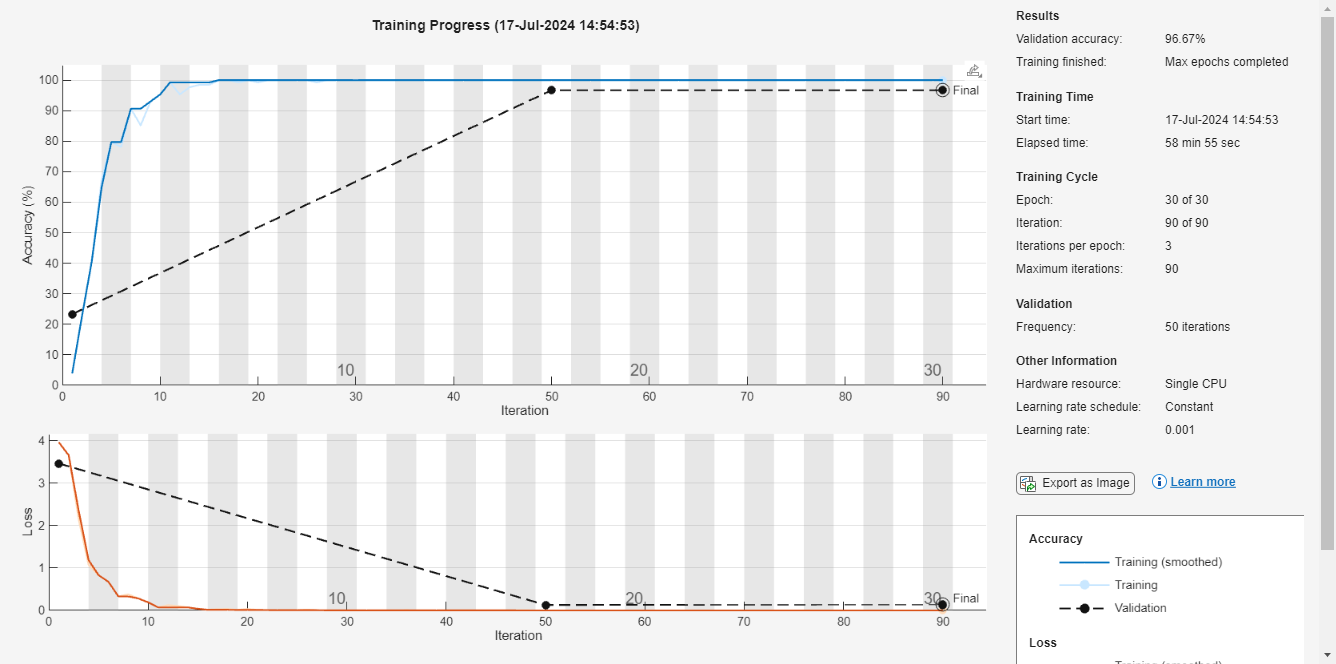

% Fasteners data set training folder
filename = "E:\Semester Pendek\MATLAB\Deep Learning for Computer Vision\Data\MathWorks Created\ASL Alphabet\Classification\Train";
imdsFasteners = imageDatastore(filename,"IncludeSubfolders",true,"LabelSource","foldernames");

% Split into training and validation data
[imdsTrain,imdsValidation] = splitEachLabel(imdsFasteners,0.8,"randomized");

% Resize to match ResNet-18's expected input size
augTrain = augmentedImageDatastore([224,224],imdsTrain);
augVal = augmentedImageDatastore([224,224],imdsValidation);

% Set training options
opts = trainingOptions("adam","ValidationData",augVal,"Shuffle","every-epoch","Plots","training-progress");

net = trainNetwork(augTrain,lgraph_2,opts);

filenameTest = "E:\Semester Pendek\MATLAB\Deep Learning for Computer Vision\Data\MathWorks Created\ASL Alphabet\Classification\Test";
imdsTest = imageDatastore(filenameTest,"IncludeSubfolders",true,"LabelSource","foldernames");

augTest = augmentedImageDatastore([224,224],imdsTest);
testPreds = classify(net,augTest);

testAccuracy = nnz(testPreds == imdsTest.Labels)/length(testPreds)

testAccuracy = 0.9458

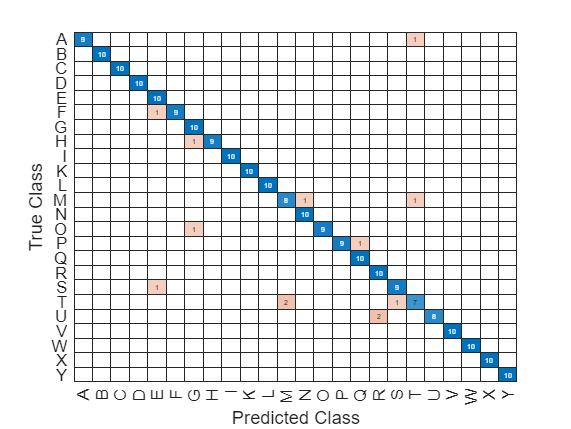

confusionchart(imdsTest.Labels,testPreds)